# Detailed Stock Analysis and Price Prediction in MATLAB

## Data Exploration

### Closing Price and Volume Analysis

First, we start by importing historical stock data for our stocks in the form of csv files to timetables. Each with 6 columns; Open, High, Low, Close, Adjusted Close and Volume. The selected stocks are AAPL: Apple, AMZN: Amazon, FB: Facebook, GOOG: Google.

clear
clc

AAPL = readtimetable('AAPL.csv');
AMZN = readtimetable('AMZN.csv');
FB = readtimetable('FB.csv');
GOOG = readtimetable('GOOG.csv');

Then we go onto resizing our data so that we only work with the days which all 5 of these companies were publicly traded. Since Facebook is the company with the most recent IPO, we resize our data according to its size.

dates = FB.Date;
AAPL = AAPL(dates,:);
AMZN = AMZN(dates,:);
GOOG = GOOG(dates,:);

Let's visualize the closing prices for each stock to get a feel for the data.

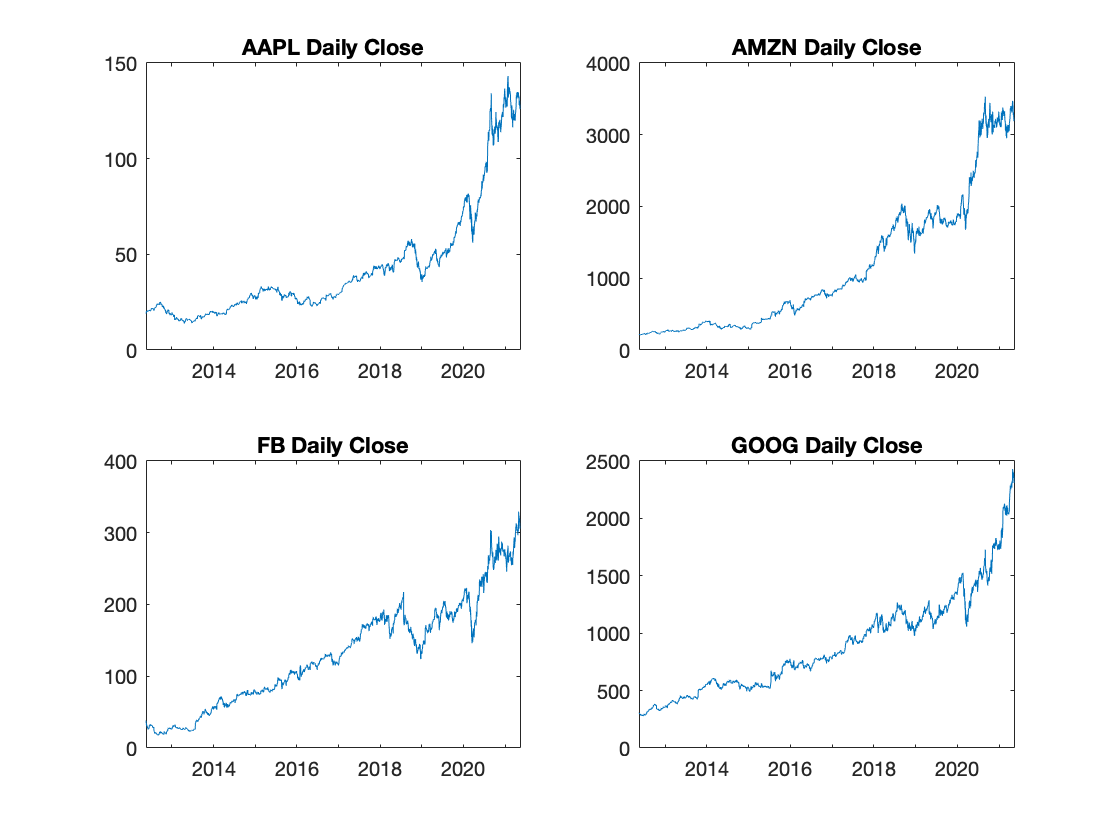

figure

subplot(2,2,1);
x = AAPL.Date;
y = AAPL.Close;
plot(x, y);
title('AAPL Daily Close');

subplot(2,2,2);
x = AMZN.Date;
y = AMZN.Close;
plot(x, y);
title('AMZN Daily Close');

subplot(2,2,3)
x = FB.Date;
y = FB.Close;
plot(x, y);
title('FB Daily Close');

subplot(2,2,4);
x = GOOG.Date;
y = GOOG.Close;
plot(x, y);
title('GOOG Daily Close');

Now that we have visualized the daily closing price for the stocks we can see that they tend to have similar trends in terms of the daily closing price. So let's visualize the daily volumes for each stock.

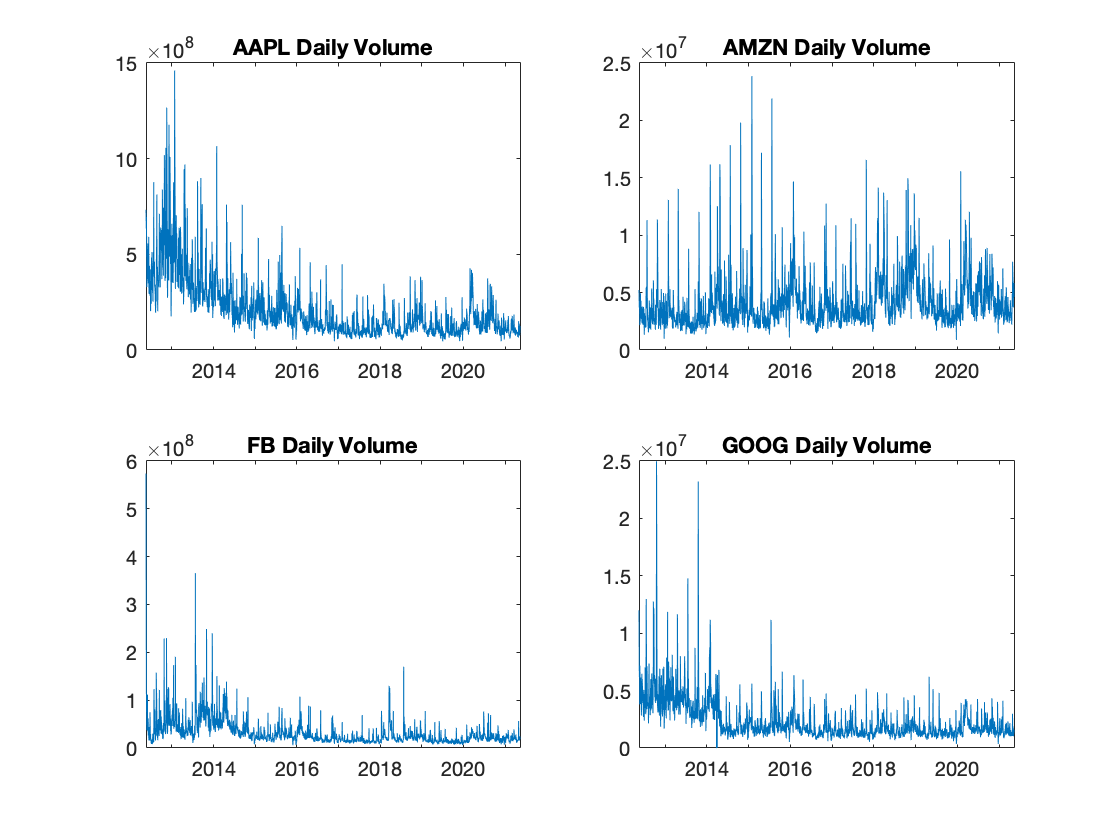

figure

subplot(2,2,1)
x = AAPL.Date;
y = AAPL.Volume;
plot(x, y);
title('AAPL Daily Volume');

subplot(2,2,2)
x = AMZN.Date;
y = AMZN.Volume;
plot(x, y);
title('AMZN Daily Volume');

subplot(2,2,3)
x = FB.Date;
y = FB.Volume;
plot(x, y);
title('FB Daily Volume');

subplot(2,2,4)
x = GOOG.Date;
y = GOOG.Volume;
plot(x, y);
title('GOOG Daily Volume');

We can see that the volumes of the stocks does not seem to correlate as much as the daily closing price. 

### Moving Average and Daily Percentage Returns Analysis

Now we are going to calculate moving averages of the Adj Close for each stock in 10 day, 20 day and 50 day intervals and add them to the timetables.

intervals = [10, 20, 50];
j = 1;
for i = intervals
    AAPL_ma(:, j) = movmean(AAPL.AdjClose, [i, 0]);
    AMZN_ma(:, j) = movmean(AMZN.AdjClose, [i, 0]);
    FB_ma(:, j) = movmean(FB.AdjClose, [i, 0]);
    GOOG_ma(:, j) = movmean(GOOG.AdjClose, [i, 0]);
    j = j + 1;
end
ma10 = AAPL_ma(:, 1);
ma20 = AAPL_ma(:, 2);
ma50 = AAPL_ma(:, 3);
AAPL = addvars(AAPL, ma10, ma20, ma50);

ma10 = AMZN_ma(:, 1);
ma20 = AMZN_ma(:, 2);
ma50 = AMZN_ma(:, 3);
AMZN = addvars(AMZN, ma10, ma20, ma50);

ma10 = FB_ma(:, 1);
ma20 = FB_ma(:, 2);
ma50 = FB_ma(:, 3);
FB = addvars(FB, ma10, ma20, ma50);

ma10 = GOOG_ma(:, 1);
ma20 = GOOG_ma(:, 2);
ma50 = GOOG_ma(:, 3);
GOOG = addvars(GOOG, ma10, ma20, ma50);

After calculating the moving averages, we are going to plot them against each stocks respective Adj Close to see how the intervals affected correlation between the two.

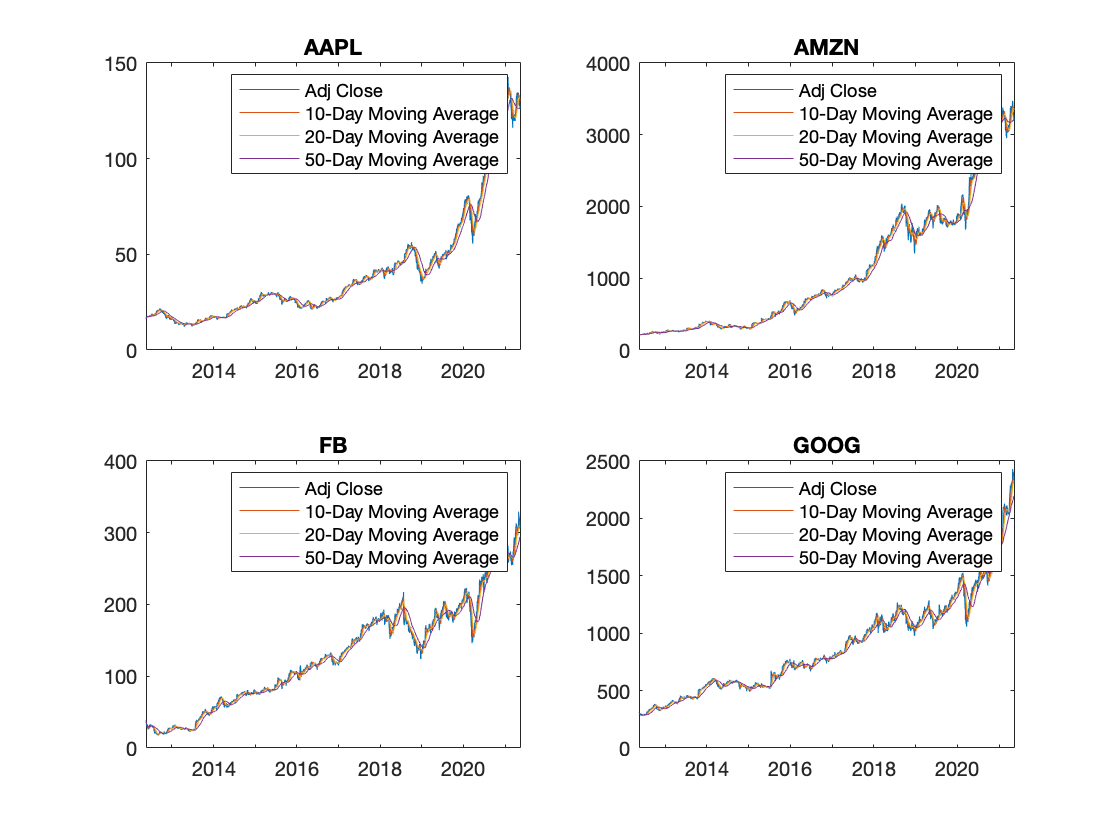

figure

subplot(2,2,1)
x = AAPL.Date;
y1 = AAPL.AdjClose;
y2 = AAPL.ma10;
y3 = AAPL.ma20;
y4 = AAPL.ma50;
plot(x, y1, x, y2, x, y3, x, y4);
legend('Adj Close', '10-Day Moving Average', '20-Day Moving Average', ...
    '50-Day Moving Average')
title('AAPL');

subplot(2,2,2)
x = AMZN.Date;
y1 = AMZN.AdjClose;
y2 = AMZN.ma10;
y3 = AMZN.ma20;
y4 = AMZN.ma50;
plot(x, y1, x, y2, x, y3, x, y4);
legend('Adj Close', '10-Day Moving Average', '20-Day Moving Average', ...
    '50-Day Moving Average')
title('AMZN');

subplot(2,2,3)
x = FB.Date;
y1 = FB.AdjClose;
y2 = FB.ma10;
y3 = FB.ma20;
y4 = FB.ma50;
plot(x, y1, x, y2, x, y3, x, y4);
legend('Adj Close', '10-Day Moving Average', '20-Day Moving Average', ...
    '50-Day Moving Average')
title('FB');

subplot(2,2,4)
x = GOOG.Date;
y1 = GOOG.AdjClose;
y2 = GOOG.ma10;
y3 = GOOG.ma20;
y4 = GOOG.ma50;
plot(x, y1, x, y2, x, y3, x, y4);
legend('Adj Close', '10-Day Moving Average', '20-Day Moving Average', ...
    '50-Day Moving Average')
title('GOOG');

Now that some baseline analysis was done, we have to dig a little deeper. Next up on the list there is risk analysis. For getting an idea about how risky a security is the most fundamental method is to check the daily return. So we are going to calculate the daily returns for our stocks.

len = length(AAPL.AdjClose);
for i = 1: (len-1)
    AAPL_Return(i) = (AAPL.AdjClose(i+1) - AAPL.AdjClose(i))/AAPL.AdjClose(i);
    AMZN_Return(i) = (AMZN.AdjClose(i+1) - AMZN.AdjClose(i))/AMZN.AdjClose(i);
    FB_Return(i) = (FB.AdjClose(i+1) - FB.AdjClose(i))/AMZN.AdjClose(i);
    GOOG_Return(i) = (GOOG.AdjClose(i+1) - GOOG.AdjClose(i))/GOOG.AdjClose(i);
    
end

### Correlation Analysis

Now that we have calculated the daily returns, it is time to visualize the new data to assess the risk of these securities.

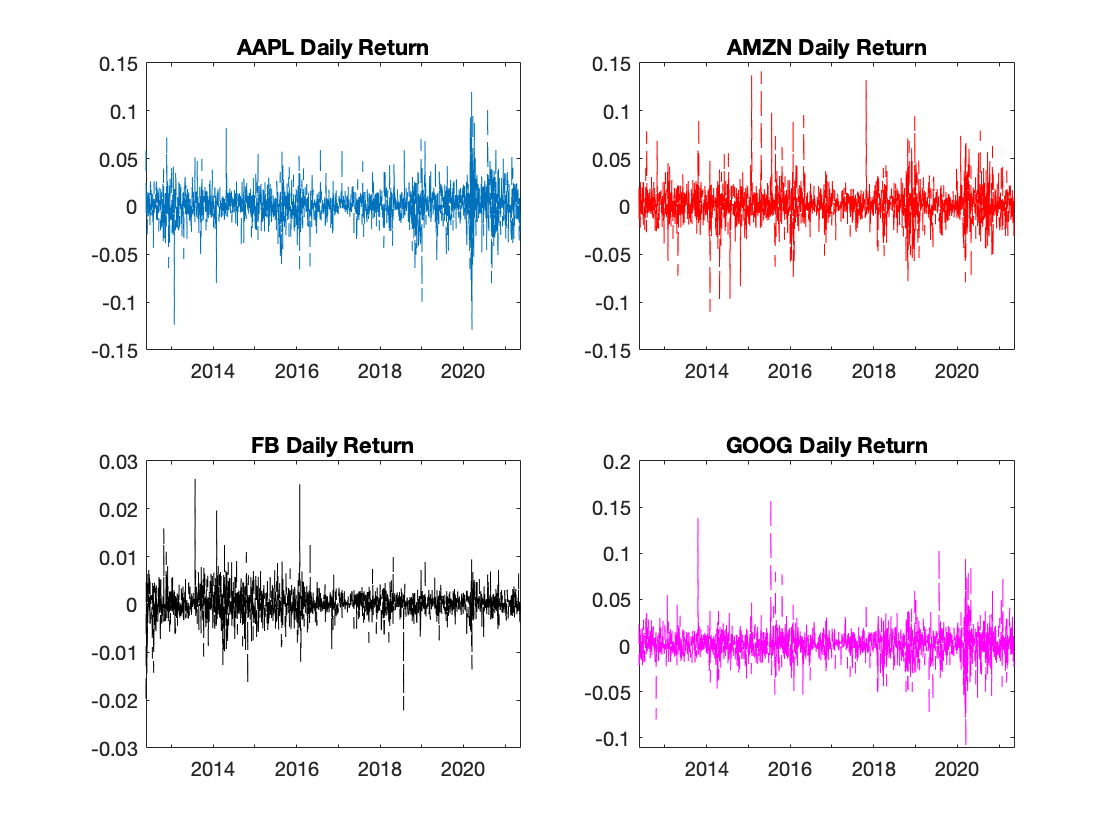

dates(1) = [];
figure

subplot(2,2,1)
plot(dates, AAPL_Return, "--");
title('AAPL Daily Return');

subplot(2,2,2)
plot(dates, AMZN_Return, "--r");
title('AMZN Daily Return');

subplot(2,2,3)
plot(dates, FB_Return, "--k");
title('FB Daily Return');

subplot(2,2,4)
plot(dates, GOOG_Return, "--m");
title("GOOG Daily Return")

These plots gave us a rough idea on how volatile and risky these stocks are but average daily returns could be better visualized with histograms. In histograms we can see how the daily returns have been distributed so we can have a better grasp on what risk these stocks carry.

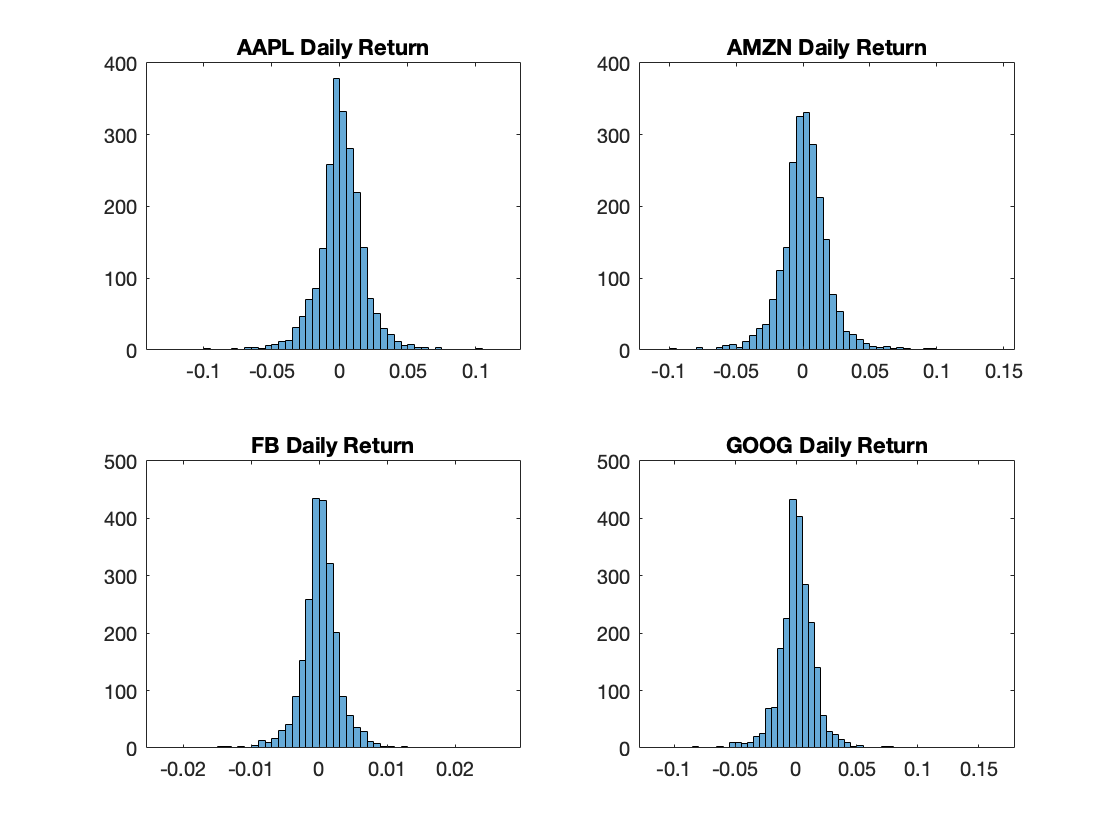

figure

subplot(2,2,1)
histogram(AAPL_Return);
title('AAPL Daily Return')

subplot(2,2,2)
histogram(AMZN_Return);
title('AMZN Daily Return')


subplot(2,2,3)
histogram(FB_Return);
title('FB Daily Return')

subplot(2,2,4)
histogram(GOOG_Return);
title('GOOG Daily Return')

As we take a look at the histograms we can see that the daily returns are fairly symmetrical about 0. We can say that these stocks are neither high or low risk but rather medium-risk.

Since we established an individual understanding for every stock let's take a look at how they correlate. The expectation is the correlation should be somewhat strong considering that these are all big tech companies.

First off, we start by creating a new timetable with all of our stocks' daily percentage returns corresponding to the date.

Date = dates;
AAPLReturn = AAPL_Return';
AMZNReturn = AMZN_Return';
FBReturn = FB_Return';
GOOGReturn = GOOG_Return';
dr = table(Date, AAPLReturn, AMZNReturn, FBReturn, GOOGReturn);
dr = table2timetable(dr, "RowTimes", "Date");

Next up, we are going to create a scatter plot and two histograms for each stock pair to visualize their correlation. Let's create the scatter histogram for AAPL and itself to see what 100% correlation looks like. Then we'll move onto the pairs.

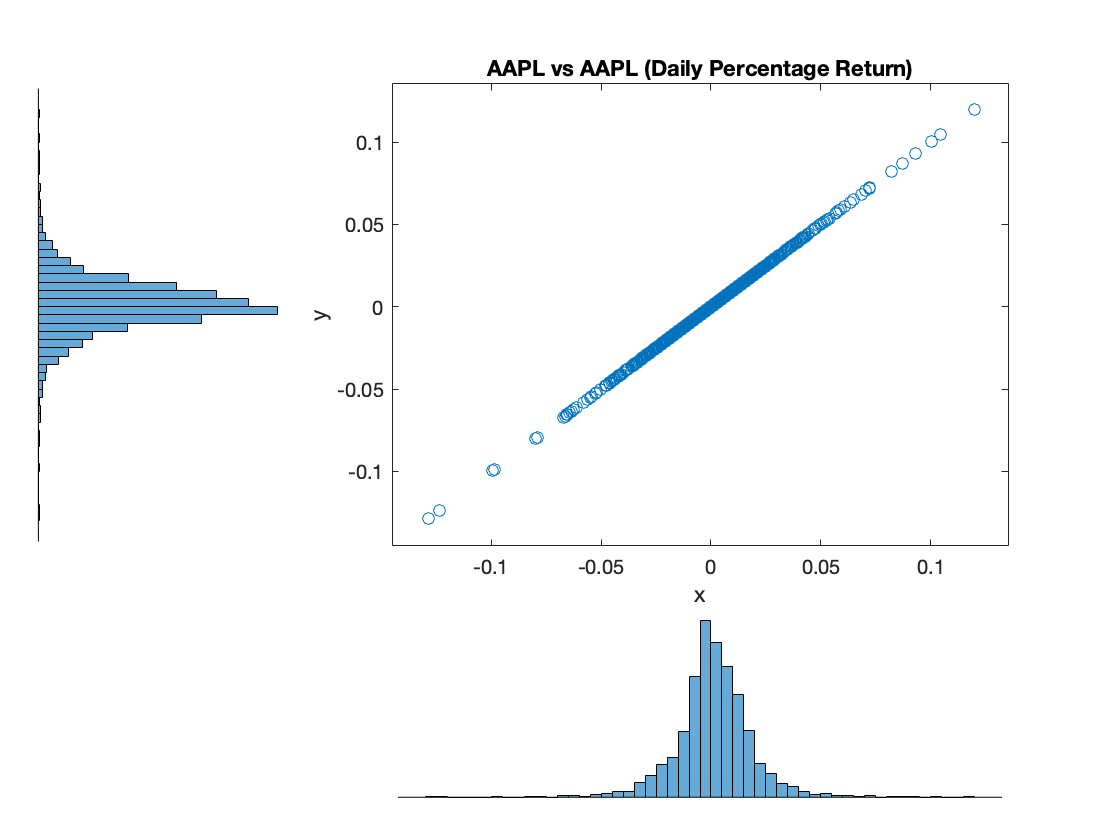

figure
scatterhist(dr.AAPLReturn, dr.AAPLReturn)
title('AAPL vs AAPL (Daily Percentage Return)');

Now that we know what perfect and positive correlation looks like, we should visualize the proper pairs to get an idea of how strongly their daily returns correlate.

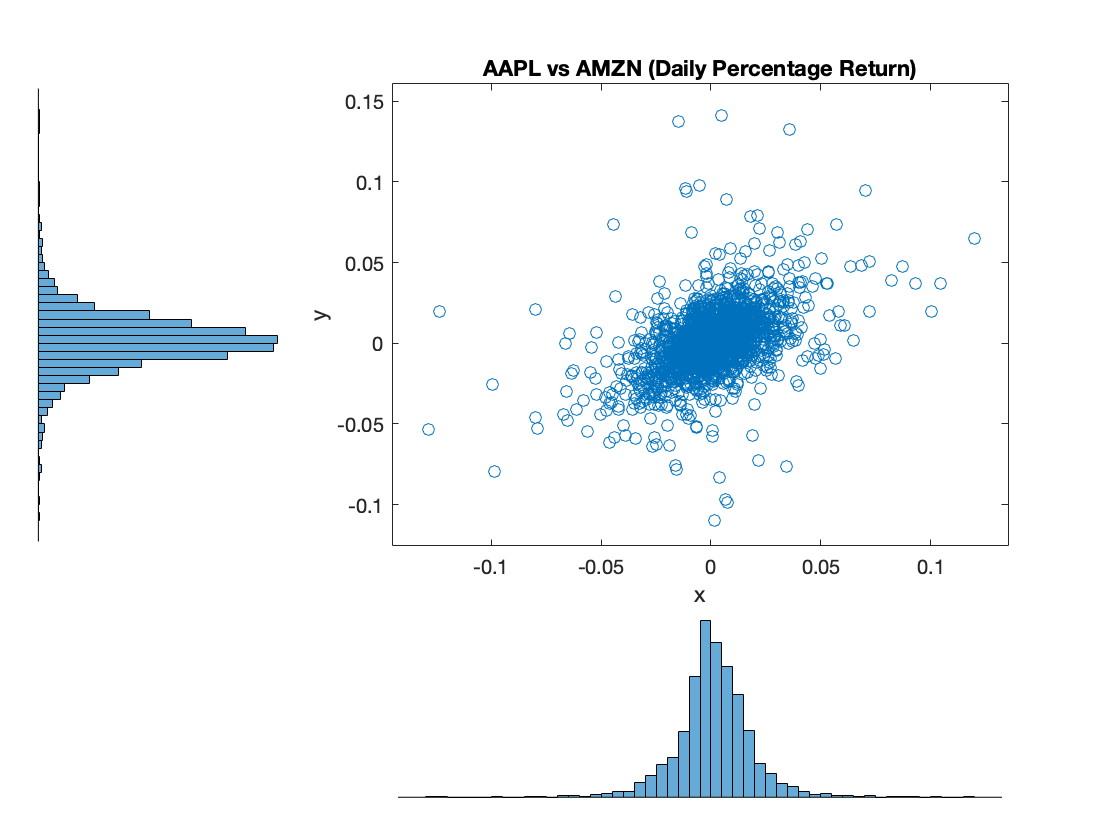

figure
subplot(3,2,1)
scatterhist(dr.AAPLReturn, dr.AMZNReturn);
title('AAPL vs AMZN (Daily Percentage Return)');

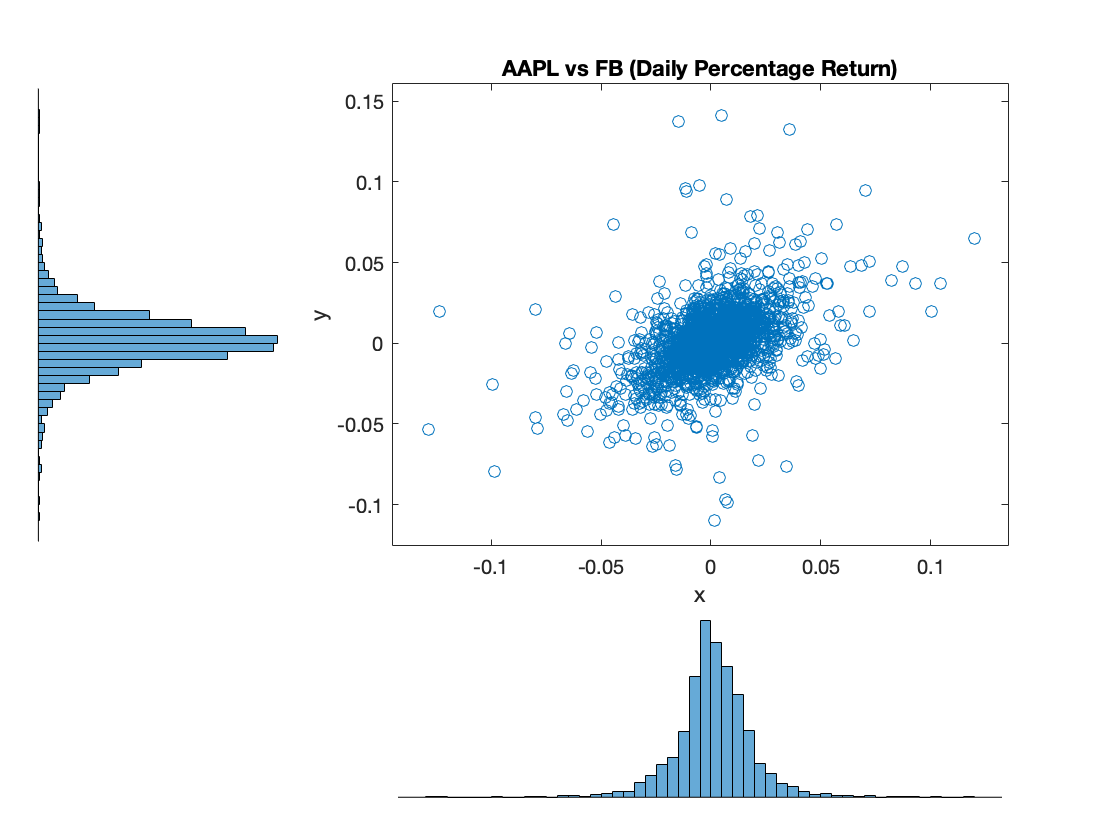

subplot(3,2,2)
scatterhist(dr.AAPLReturn, dr.AMZNReturn);
title('AAPL vs FB (Daily Percentage Return)');

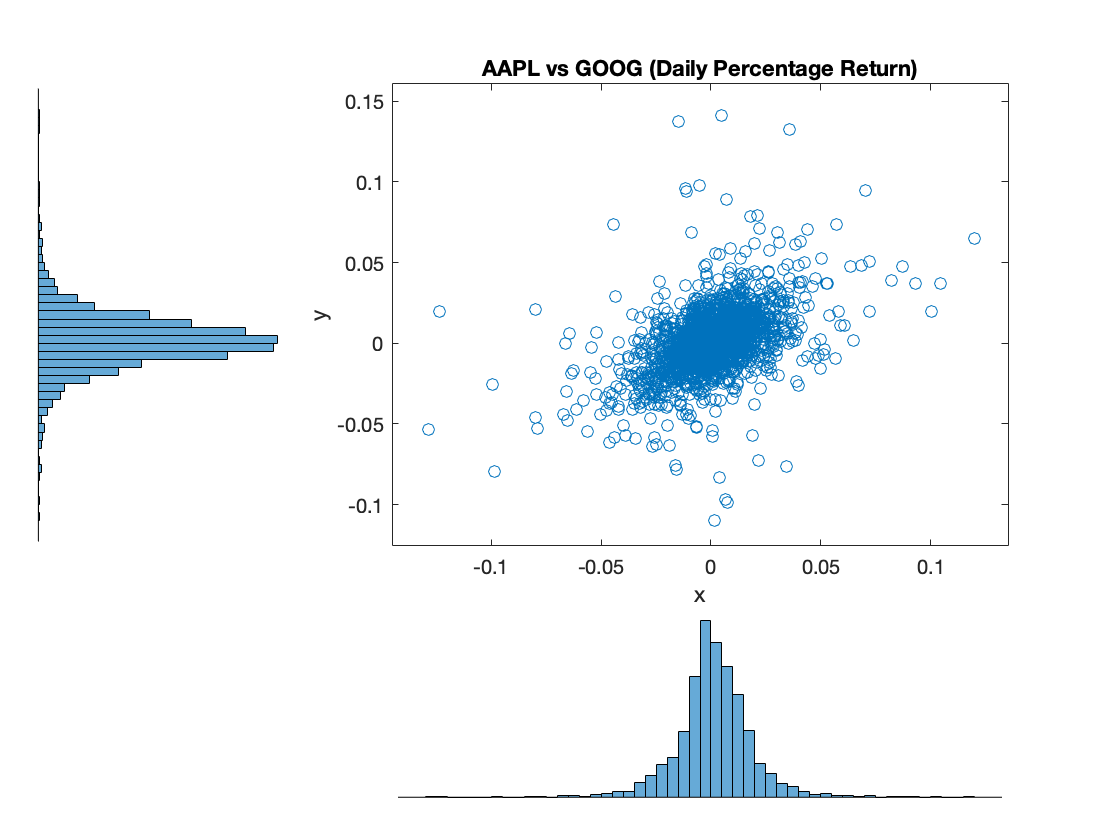

subplot(3,2,3)
scatterhist(dr.AAPLReturn, dr.AMZNReturn);
title('AAPL vs GOOG (Daily Percentage Return)');

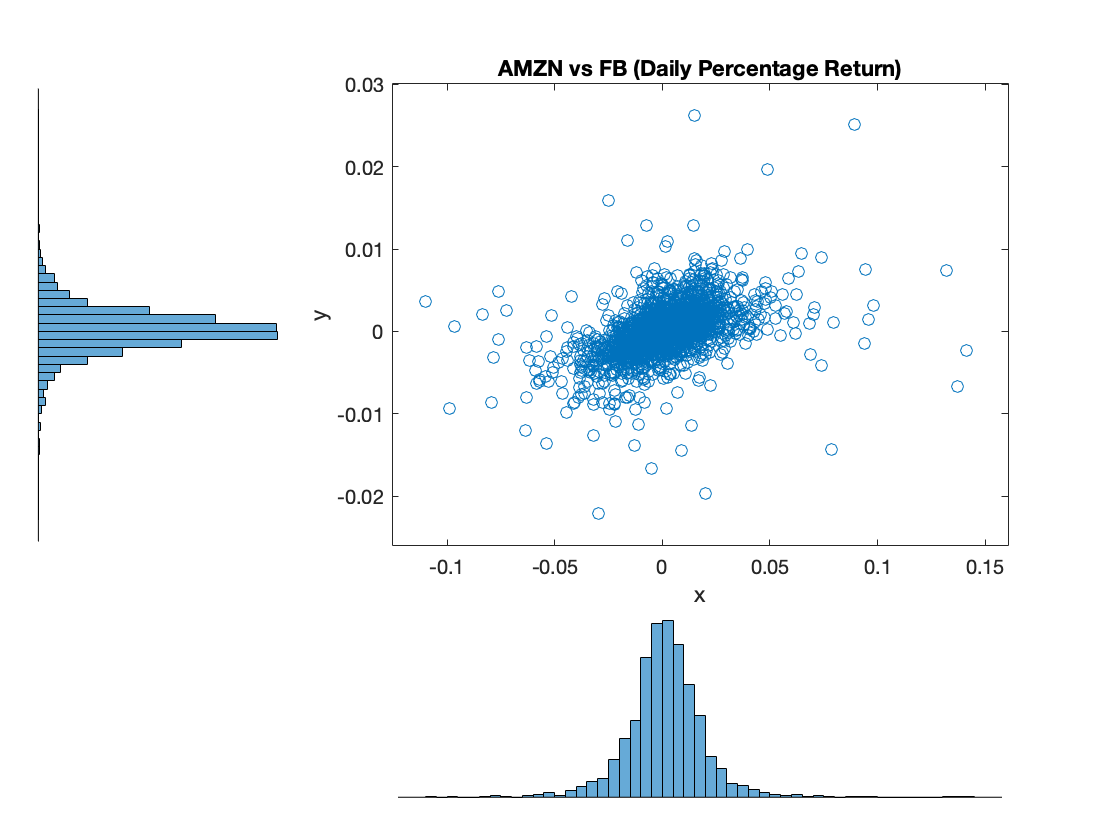

subplot(3,2,4)
scatterhist(dr.AMZNReturn, dr.FBReturn);
title('AMZN vs FB (Daily Percentage Return)');

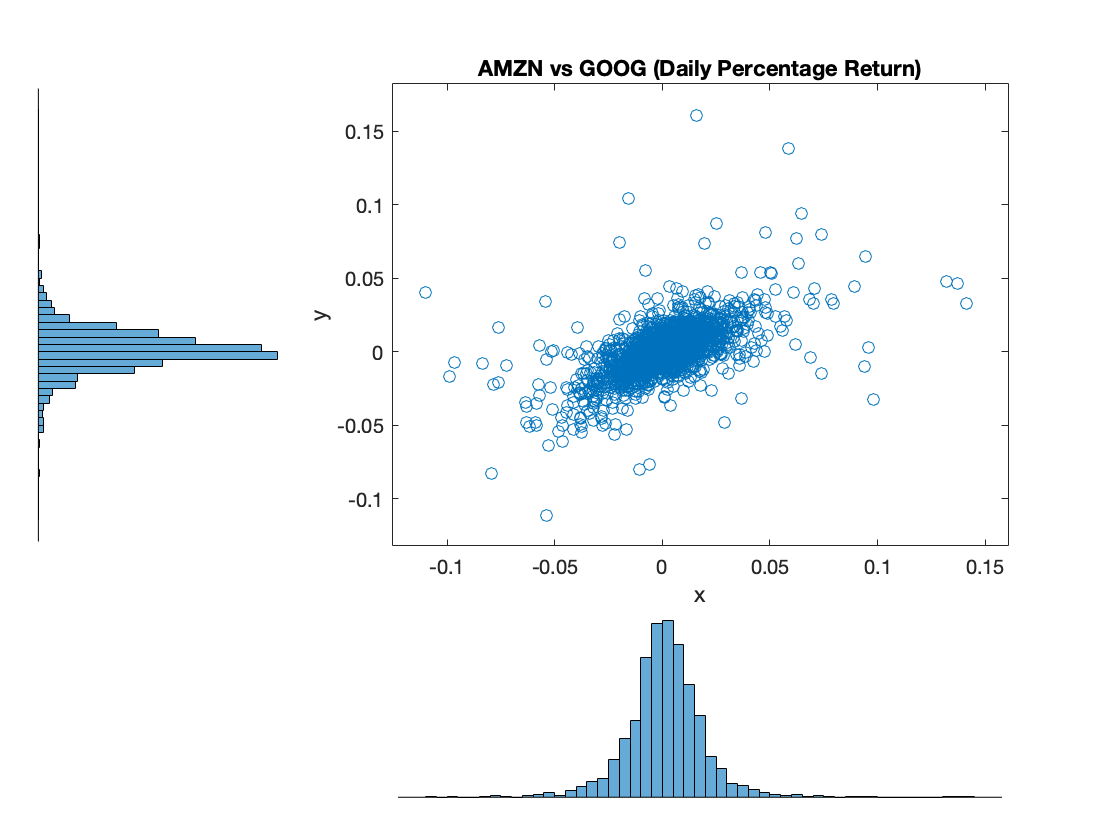

subplot(3,2,5)
scatterhist(dr.AMZNReturn, dr.GOOGReturn);
title('AMZN vs GOOG (Daily Percentage Return)');

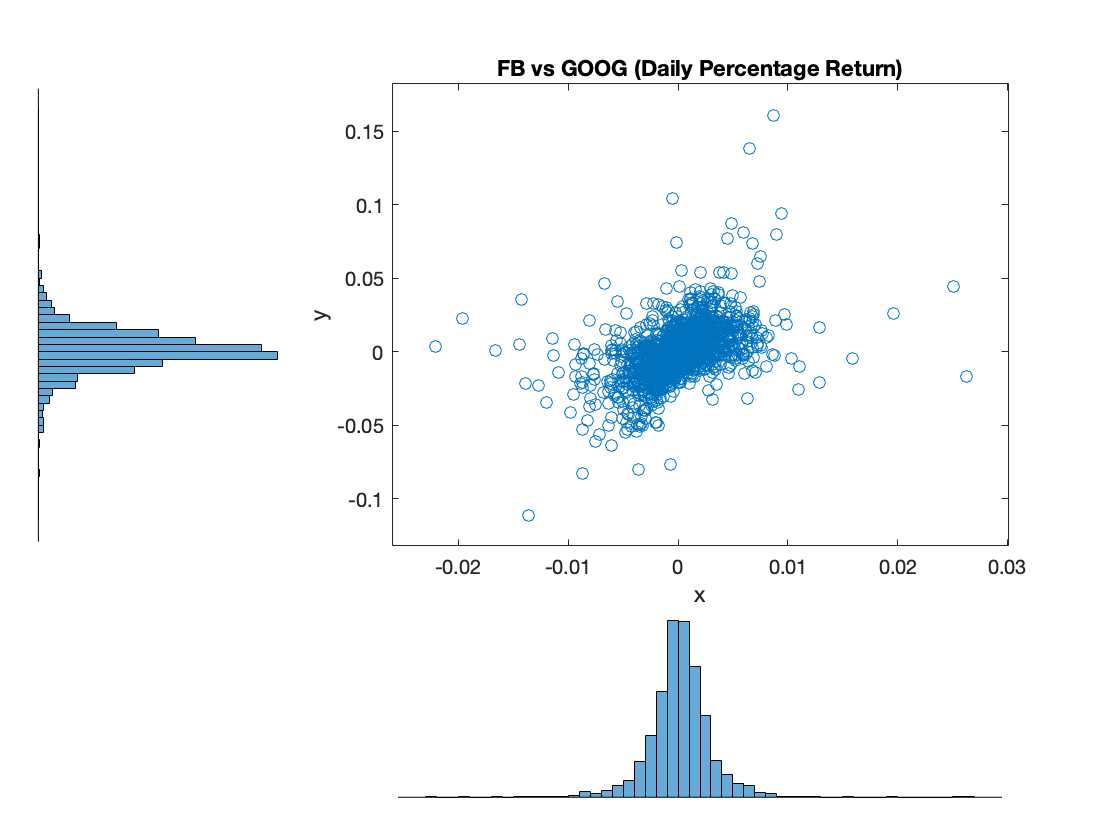

subplot(3,2,6)
scatterhist(dr.FBReturn, dr.GOOGReturn);
title('FB vs GOOG (Daily Percentage Return)');

Looking at the scatter histograms for the pairs we can see the correlation between the AMZN-GOOG is the strongest and AAPL-GOOG trails just behind. However we can safely say that all pairs are somewhat strongly positive correlated in terms of their daily percentage returns.

We should have a good understanding of the data by now. Let's just visualize the correlation one last time using a correlation plot to see the correlation coefficients on top of the respective pairs.

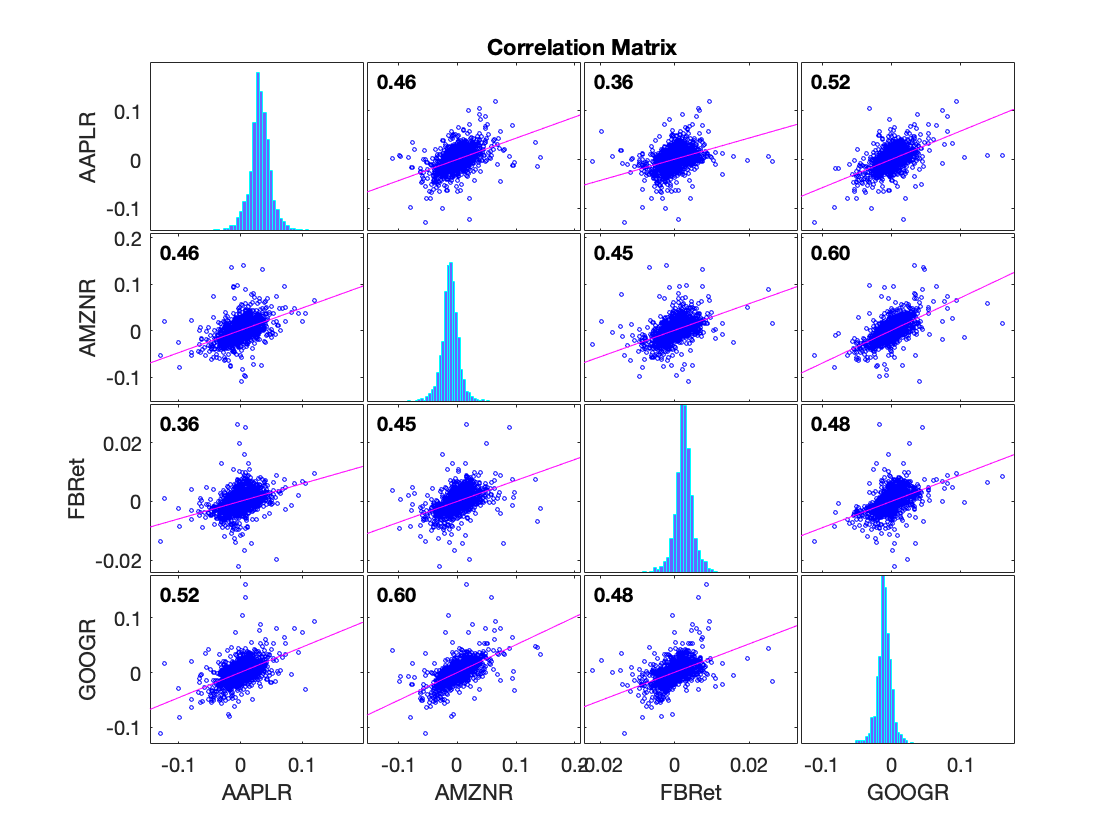

corrplot(dr)

Interpreting the correlation plot we can see that our guesses based on the scatter histograms were correct AMZN-GOOG have a 0.6 correlation coefficient while AAPL-GOOG trails just behind with 0.52. Every pair has a positive correlation coefficient which means that their trends tend to follow each other. If you want to diversify your portfolio investing in tech stocks while you are already invested in them is probably not a good idea.

## Price Prediction with Machine Learning

### Price Prediction for GOOG using LSTM Networks

I chose GOOG as the stock for this section because it is overall the highest correlated with the other stocks. In this section we are going to use LSTM (Long-Short Term Memory) Network which is a special kind of RNN (Recurrent Neural Network).

First off we start by creating a column vector with only the closing prices of GOOG since that is the feature we are trying to predict. And then we divide the data into training and testing datasets.

data = GOOG.Close';
training_len = floor(length(data)*0.95);

Now we standardize the data.

mu = mean(data);
sig = std(data);

dataStandardized = (data-mu)/sig;
trainDataStandardized = dataStandardized(1:training_len);

Since what we are doing is technically time series forecasting we have to prepare predictors responses. Here we create vectors of data which are shifted by one day for the LSTM Network.

XTrain = trainDataStandardized(1: end-40);
YTrain = trainDataStandardized(41: end);

Now we define our LSTM regression networks architecture. We specify our LSTM to have 200 hidden units.

numFeatures = 1;
numResponses = 1;
numHiddenUnits = 300;

layers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(numResponses)
    regressionLayer];

All that is left before training our dataset is to set the options of our RNN. We set max epochs to 250 to prevent the gradients from exploding. We set the gradient threshold to 1 and the initial learning to 0.005, and drop the learn rate after 125 epochs by multiplying by a factor of 0.2.

options = trainingOptions('adam', ...
    'MaxEpochs', 500, ...
    'GradientThreshold',1, ...
    'InitialLearnRate',0.0025, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',125, ...
    'LearnRateDropFactor',0.2, ...
    'Verbose',0, ...
    'Plots','training-progress');

Training our LSTM network!

net = trainNetwork(XTrain, YTrain, layers, options);

### Testing the LSTM Network

Now that our LSTM Network is trained using our training dataset, lets try to predict the price of the GOOG stock with it and compare the results to real prices.

testDataStandardized = dataStandardized(training_len+1 : end);
Xtest = testDataStandardized(1: end-1);

We first predict on the training datasets Xtrain and Ytrain to initialize the network state. Then we loop over the remaining predictions and update the predictAndUpdateState with the previous prediction since our time step is one day.

The execution environment is set to CPU because the data is not rather large. 

net = predictAndUpdateState(net,XTrain);
[net,YPred] = predictAndUpdateState(net,YTrain(end));

numTimeStepsTest = numel(Xtest);
for i = 2:numTimeStepsTest
    [net,YPred(:,i)] = predictAndUpdateState(net,YPred(:,i-1),'ExecutionEnvironment','cpu');
end

Next, we unstardadize the predictions for it to be comparable to the real prices and we calculate the root mean square error.

YPred = sig * YPred + mu;
YTest = GOOG.Close(end-111: end);
rmse = sqrt(mean((YPred-YTest).^2))

rmse = 1×112 single row vector
  444.4370  422.5343  429.3501  441.0058  445.7213  444.0899  440.6850  438.4481  437.5607  437.1391  436.5439  435.6802  434.7162  433.7966  432.9583  432.1761  431.4226  430.6902  429.9839  429.3099  428.6699  428.0623  427.4853  426.9369  426.4160  425.9216  425.4529  425.0084  424.5869  424.1873  423.8080  423.4485  423.1074  422.7837  422.4764  422.1848  421.9077  421.6446  421.3946  421.1569  420.9309  420.7158  420.5111  420.3163  420.1307  419.9541  419.7855  419.6248  419.4717  419.3256


We plot the real prices and the predictions on top of each other.

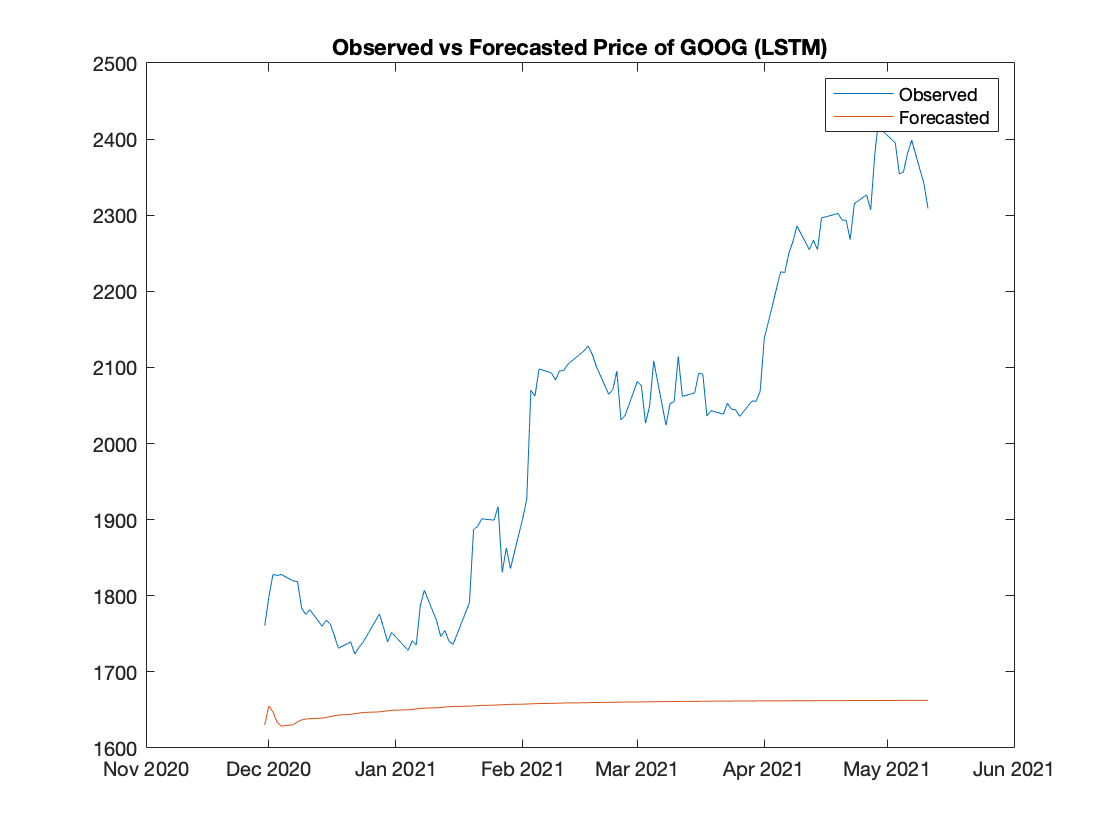

dates = GOOG.Date(end-111: end);

figure
plot(dates, YTest, dates, YPred')
legend('Observed', 'Forecasted');
title('Observed vs Forecasted Price of GOOG (LSTM)');

As it can be seen on the graph our LSTM model output satisfactory results in terms of predicting the trend of the stock in relatively short terms. However we could try another approach to combine with LSTM Network when investing to get a better idea about a stock's forecasting.

### Price Prediction for GOOG Using ARIMA

ARIMA (Autoregressive Integrated Moving Average) is a model used in statistics and econometrics to forecast the behaviour of time series. ARIMA is better fitted for short-term forecasting compared to LSTM. 

First we start by checking if the data auto-correlates with it's lagged self.

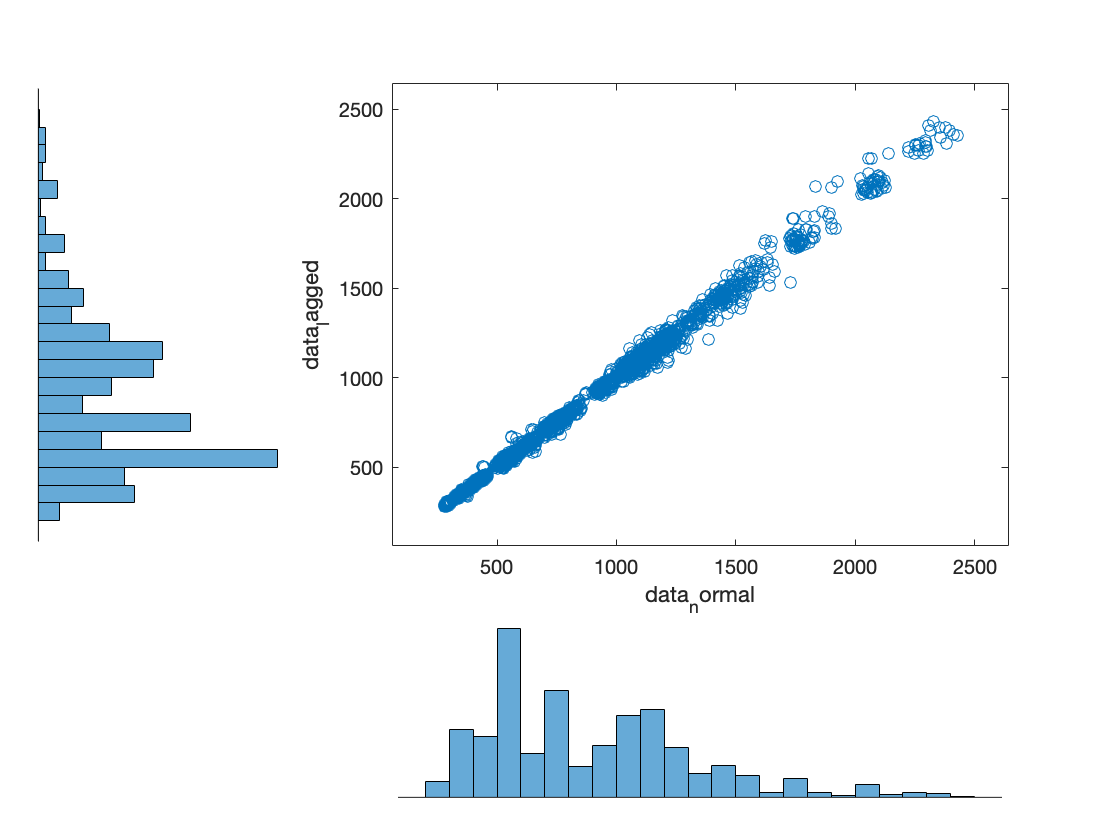

data_normal = GOOG.Close(1: end-3);
data_lagged = GOOG.Close(4: end);

scatterhist(data_normal, data_lagged);

We can see that the data higly auto-correlates so we can assume that this model's going to produce better results than the previous. 

Next, we create the ARIMA(1,1,1) model and fit our data to the model.

Mdl = arima(1,1,1);
idxpre = 1: Mdl.P;
idxest = (Mdl.P+1) : 1759;
EstMdl = estimate(Mdl, GOOG.Close(idxest),...
    'Y0', GOOG.Close(idxpre));

 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant     0.83603       0.46914          1.782        0.074742
    AR{1}       -0.67696        0.1476        -4.5865      4.5069e-06
    MA{1}         0.7193       0.14072         5.1115      3.1955e-07
    Variance      127.92        1.7302         73.936               0



Now, we forecast the closing values for the last 500 day window of our observed prices.

yf0 = GOOG.Close(idxest(end-1: end));
yf = forecast(EstMdl, 500, yf0);

Let's plot to see how our ARIMA model performed.

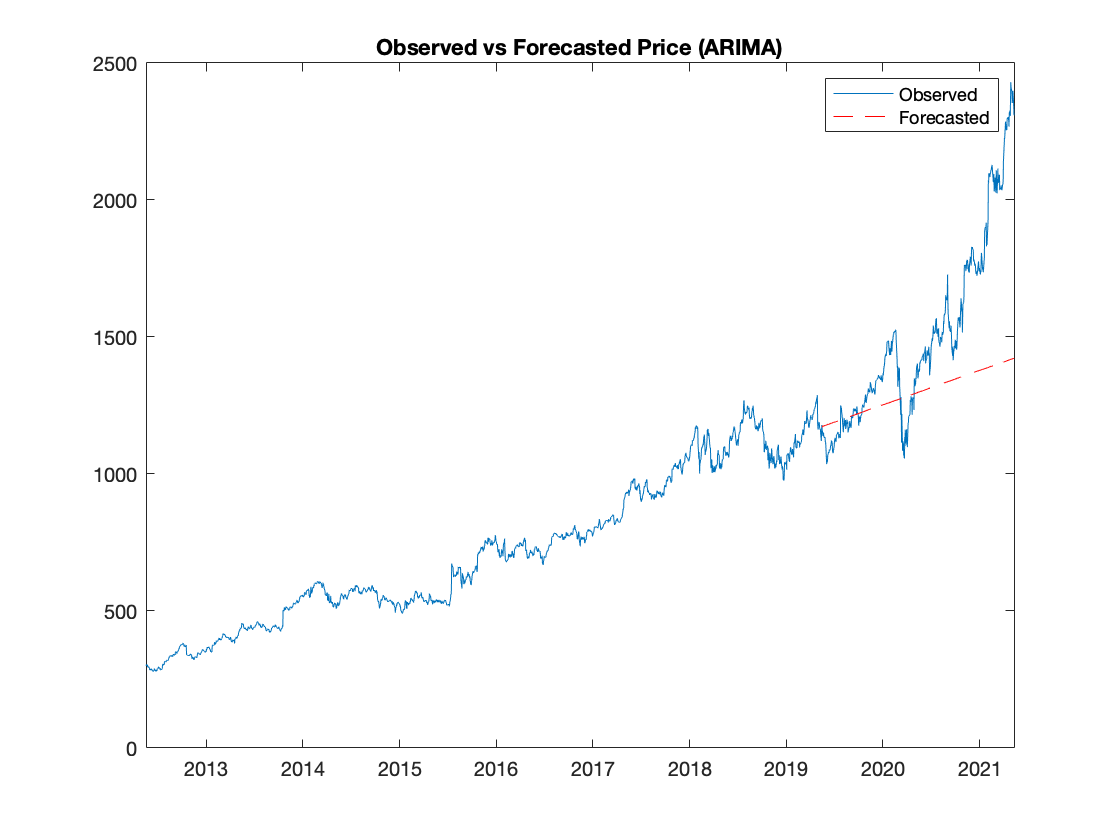

date1 = GOOG.Date;
date2 = GOOG.Date(end-499: end);

figure
plot(date1, GOOG.Close);
hold on
plot(date2, yf, '--r');
title('Observed vs Forecasted Price (ARIMA)');
legend("Observed", "Forecasted");
hold off

As seen on the graph  the ARIMA model the trend was not accurately predicted but the price points are somewhat accurate even though the predictions look linear.

### Summary

With limited computing power, we were able to explore the stock data, find correlations between pairs perform deep learning with LSTM to see what the trend was going to be and use machine learning model ARIMA to regress the forecasting prices.

As an investor I probably would use the LSTM model to predict whether the security is going to go up or down and the ARIMA model to roughly predict the price points.

#### Written by Uzay Karadağ